close all;
clc;
clear;

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/PLSDA/Mouse_Plasma_Data/";

numMetadataRows = 11;

file_name = "Difference_Spectra.csv";
file_path = data_path+file_name;
Dif_Spectra = readmatrix(file_path);

file_name = "Loadings.csv";
file_path = data_path+file_name;
Loadings = csvread(file_path, numMetadataRows, 0);

file_name = "Wavenumbers.csv";
file_path = data_path+file_name;
corr_shifts = readmatrix(file_path);

LV_1 = Loadings(:,4)';
LV_2 = Loadings(:,5)';
Norm_Dif_Spectra = -30*Dif_Spectra;

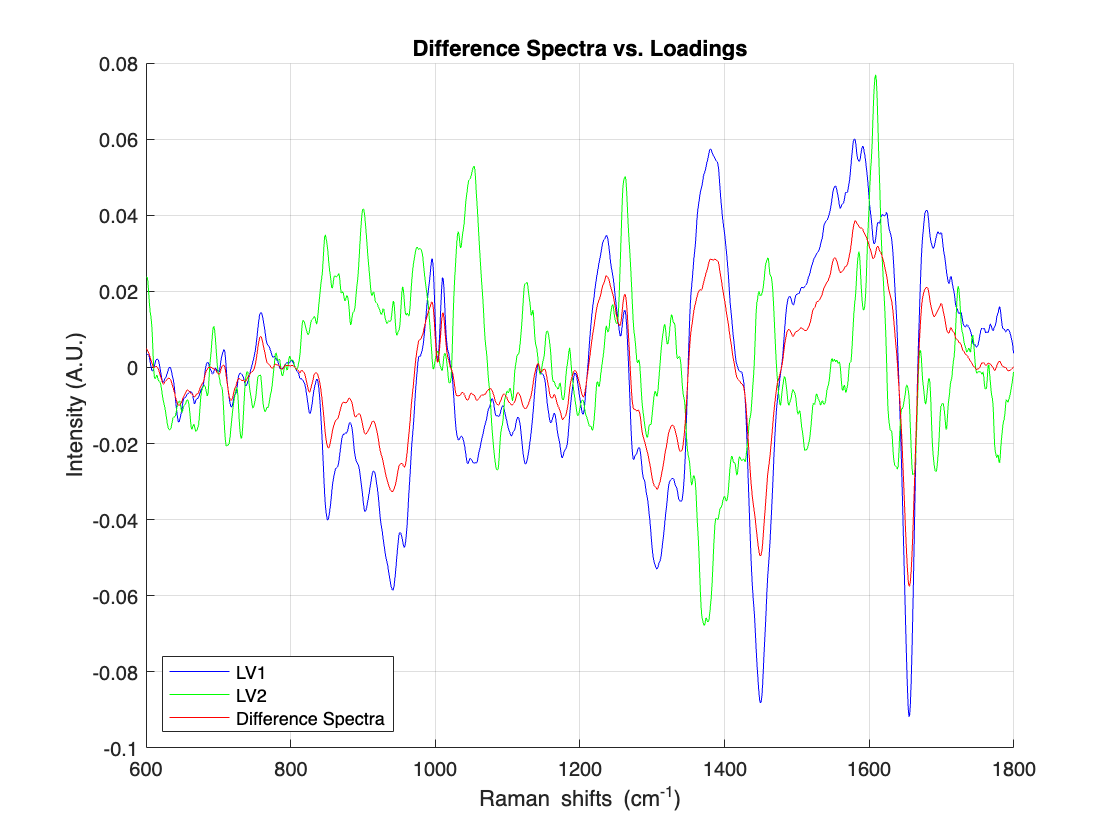

% Plotting Loadings and Difference Spectra

figure;
hold on;
grid on;
plot(corr_shifts(101:end), LV_1(101:end), '-b');
plot(corr_shifts(101:end), LV_2(101:end), '-g');
plot(corr_shifts(101:end), Norm_Dif_Spectra(104:end), '-r');
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Difference Spectra vs. Loadings');
legend('LV1', 'LV2', 'Difference Spectra', 'Location', 'southwest');